# Eksamen 2015E Løsning

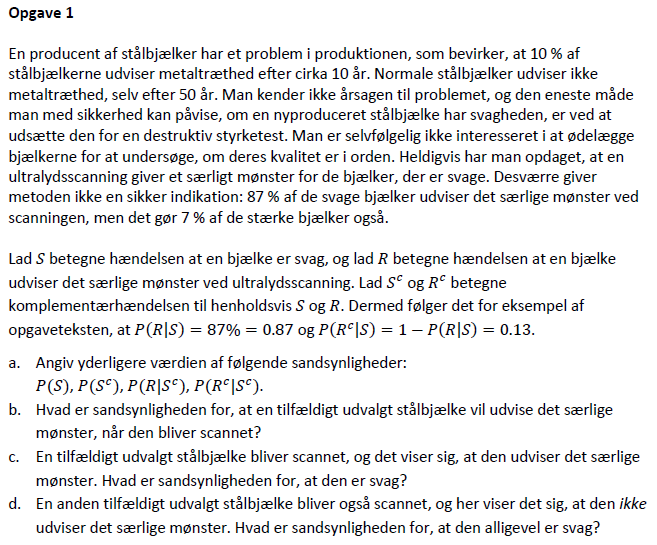

clc; clear all;

% Data fra opgaven
pR_S = 0.87;         % Bjælken udviser mønstret, givet den er svag
rRc_S = 1 - pR_S;    % Bjælken udviser IKKE mønstret, givet den er svag

% Opgave a
pS = 0.10;          % Ssh for svag bjælke. Givet fra opgaven
pSc = 1 - pS;       % P ikke svag - altså stærk
pR_Sc = 0.07;       % Ssh for den viser mønster og ikke er svag. Givet fra opgaven
pRc_Sc = 1 - pR_Sc; % Ssh for den ikke udviser mønster givet den er stærk


% Opgave b - Totale lov om ssh
pR = pR_S * pS + pR_Sc * pSc    % Ssh for udviser mønster og er svag plus udviser mønster og er stærk

pR = 0.1500


% Opgave c - bayes lov
pSR = pR_S * pS / pR      % Ssh for den scannes og er svag

pSR = 0.5800


% Opgave d - komplimentær værdier i bayes lov
pR_Sc = rRc_S * pS/(1 - pR)

pR_Sc = 0.0153

## Opgave 2

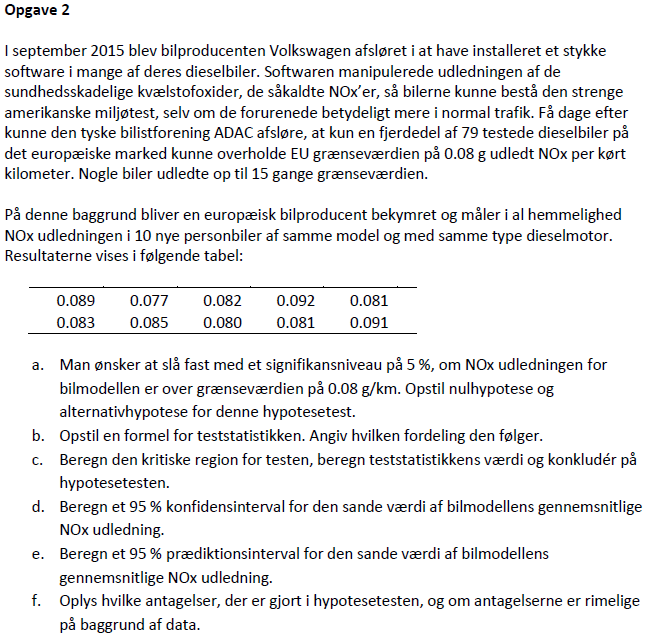

clc; clear all;

% data indlæses
data = xlsread("M4STI1_2015E_data.xlsx","A:A");

x = data';
KonfidensIntervalNormal(x, 95, [],0.08)

Da populations-standardafvigelsen er ukendt, følger stikprøvenStudents-t fordeling, med n-1 frihedsgrader, hvor n er antal værdier i stikprøven
Stikprøvemiddelværdien beregnes


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

y_bar_x = 0.0841

Stikprøvestandardafvigelsen beregnes


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

s_val = 0.0050

t-værdien findes


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\left(\frac{\alpha }{2}\,n-1\right)$$

test_vals =    -2.2622
    2.2622


Øvre konfidensinterval værdi


$$\bar{y}+\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

upper_t = 0.0877

Nedre konfidensinterval værdi


$$\bar{y}-\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

lower_t = 0.0805

Teststørrelsen udregnes, til sammenligning


$$t=\frac{\bar{y}-\mu_{0}}{s\,\sqrt{n}}$$

test = 2.5822

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     0.0805     "t nedre"      -2.2622      "y_bar"        0.0841  
    "Øvre"      0.0877     "t øvre"        2.2622      "s"         0.0050211  



[h,p,ci,stats] = ttest(data,0.08,"Tail","right","Alpha",0.05)

h = 1

p = 0.0148

ci =     0.0812
       Inf


stats = struct with fields:
    tstat: 2.5822
       df: 9
       sd: 0.0050



x = -stats.tstat*1.5:0.1:stats.tstat*1.5

x =    -3.8733   -3.7733   -3.6733   -3.5733   -3.4733   -3.3733   -3.2733   -3.1733   -3.0733   -2.9733   -2.8733   -2.7733   -2.6733   -2.5733   -2.4733   -2.3733   -2.2733   -2.1733   -2.0733   -1.9733   -1.8733   -1.7733   -1.6733   -1.5733   -1.4733   -1.3733   -1.2733   -1.1733   -1.0733   -0.9733   -0.8733   -0.7733   -0.6733   -0.5733   -0.4733   -0.3733   -0.2733   -0.1733   -0.0733    0.0267    0.1267    0.2267    0.3267    0.4267    0.5267    0.6267    0.7267    0.8267    0.9267    1.0267




lower = find(x < -stats.tstat)

lower =      1     2     3     4     5     6     7     8     9    10    11    12    13


upper = find(x > stats.tstat)

upper =     66    67    68    69    70    71    72    73    74    75    76    77    78


pd_ki = makedist("Normal","mu", 0,"sigma", 1)

pd_ki =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


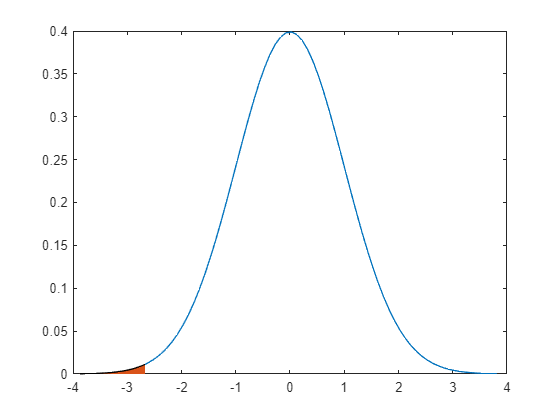


pd = pdf(pd_ki,x);

plot(x, pd)
hold on

area(x(1:length(lower)), pd(1:length(lower)))
hold off